% Setup
format compact

%Variables
tau = 0.3;
K = 55;
Kpot = 1.62;
Ktac = 0.017;
Kp = 728/275;
Kpa = 3;
Ki = 678/55;
Kia = 12;
Kd = 43/495;
Kda = 0.09;
%F.T.
G = tf([K*Kpot*Kd K*Kpot*Kp K*Kpot*Ki], [2.7 9+K*Kpot*Kd K*Kpot*Kp K*Kpot*Ki])

G =
 
       7.74 s^2 + 235.9 s + 1098
  ------------------------------------
  2.7 s^3 + 16.74 s^2 + 235.9 s + 1098
 
Continuous-time transfer function.



Ga = tf([K*Kpot*Kda K*Kpot*Kpa K*Kpot*Kia], [2.7 9+K*Kpot*Kda K*Kpot*Kpa K*Kpot*Kia])

Ga =
 
       8.019 s^2 + 267.3 s + 1069
  ------------------------------------
  2.7 s^3 + 17.02 s^2 + 267.3 s + 1069
 
Continuous-time transfer function.



%%dcgain(G)
%%zpk(G)
pole(G)

ans =   -0.6000 + 9.0000i
  -0.6000 - 9.0000i
  -5.0000 + 0.0000i


pole(Ga)

ans =   -0.9652 + 9.4671i
  -0.9652 - 9.4671i
  -4.3729 + 0.0000i


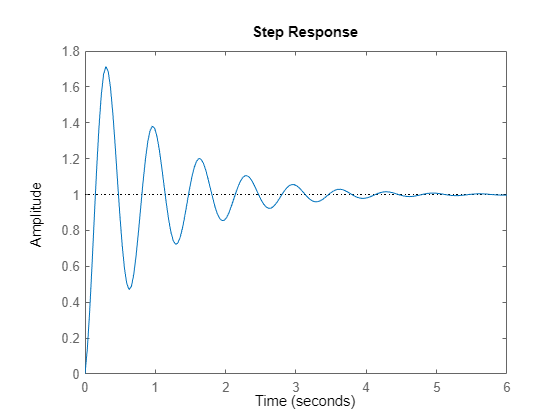

step(Ga);

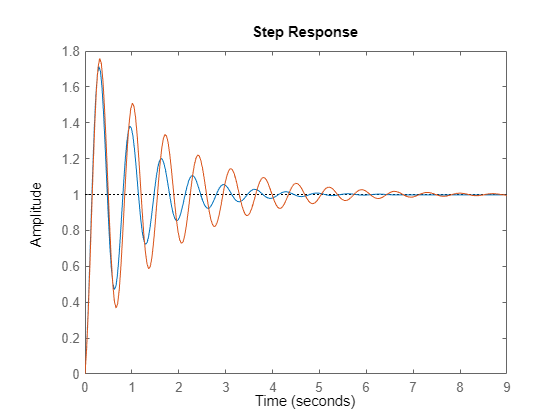

step(Ga,G);

W = tf([2*K*Ktac 5*K*Ktac], [0.27 2*K*Ktac+1 5*K*Ktac])

W =
 
       1.87 s + 4.675
  -------------------------
  0.27 s^2 + 2.87 s + 4.675
 
Continuous-time transfer function.



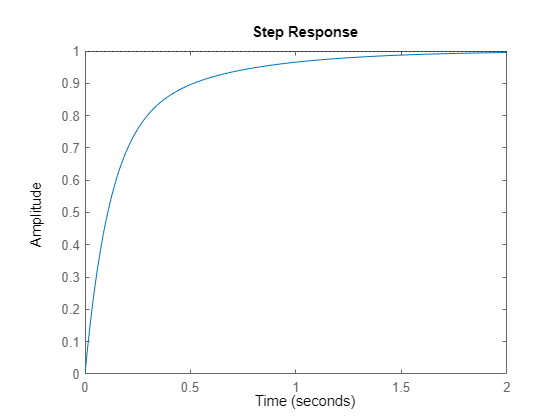

step(W);

W = tf([2*K*Kpot 5*K*Kpot], [9*0.27 9 2*K*Kpot 5*K*Kpot])

W =
 
           178.2 s + 445.5
  ----------------------------------
  2.43 s^3 + 9 s^2 + 178.2 s + 445.5
 
Continuous-time transfer function.



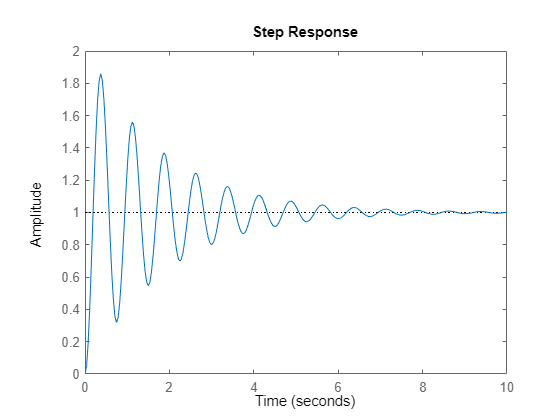

step(W);